# Numerical Methods for Optimization and Control Theory

## Daniel Kuknyo - Assignment 2

Assigned tasks: 1, 5, 10, 12

## Let's define the function we are testing

% Rosenbrock function
clc; clear all;
rr =  [-1.0, 1.2, -0.2, 1.2]; % Recommended region
f=@(x) 100.*(x(2)-x(1).^2).^2+(1-x(1)).^2;
df=@(x) [400.*x(1).^3-400.*x(1).*x(2)+2.*x(1)-2;200.*(x(2)-x(1).^2)];
ddf=@(x) [1200.*x(1).^2-400.*x(2)+2 -400.*x(1);-400.*x(1) 200];

## Plot the results

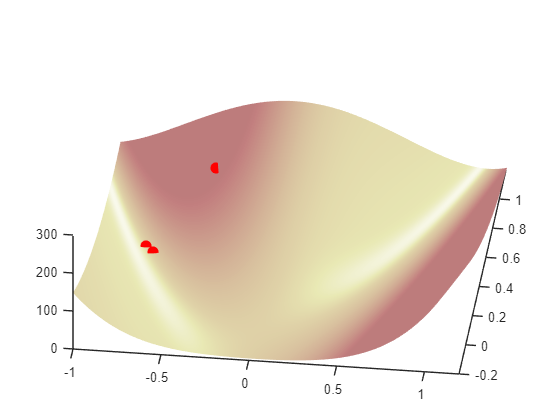

pts = plot_BFGS(@QN_BFGS, f, df, ddf, 30, [-0.4; 0.93], rr(1), rr(2), rr(3), rr(4), 256);

## Functions

function pts = plot_BFGS(G, f, df, ddf, testpts, x0, a, b, c, d, res)
    X = linspace(a,b,res);
    Y = linspace(c,d,res);
    [X,Y] = meshgrid(X,Y);
    Z = zeros(res,res);
    
    % Get the values for the Rosenbrock function
    for i=1:res
        for j=1:res
            Z(i,j) = f([X(i,j),Y(i,j)]);
        end
    end

    % Run BFGS search and retrieve a vector of [x;y] points
    pts = G(f, df, ddf, x0, testpts);
    
    figure; hold on;
    
    % Plot the function
    surfl(X,Y,Z);
    colormap("pink");
    shading interp;

    % Plot the points found by the method
    for i=1:size(pts, 2)
        px = pts(1, i);
        py = pts(2, i);
        pz = f([px, py]);
        plot3(px, py, pz,  '.', ...
            'MarkerSize', 25, ...
            'MarkerEdgeColor', 'red', ...
            'MarkerFaceColor', [1 .6 .6]);
    end
    
    xlim([a b]);
    ylim([c d]);
    view([7 61]);
    hold off;
end

function [pts] = QN_BFGS(f, df, ddf, x0, iter)
    eps=1e-12;
    n = size(x0, 1);
	S = eye(n, n);
    x = x0;
    pts = [x];
    g = df(x);
    p = -g;
    for k = 1:iter
        if norm(g)>eps
            fdir = @(t) f(x + t*p);
            dfdir = @(t) df(x + t*p);
            ddfdir = @(t) ddf(x + t*p);
            tmax = eps;
            
            while(fdir(tmax) < fdir(tmax/2))
                tmax = 2 * tmax;
            end

            v = log(eps/tmax)/log(2/3);
            gamma = fibonacci_search(fdir, 0, 0, 0, 0, tmax, v); % Find the gamma 

            p = gamma * p;
            x = x + p;
            pts = [pts, x];
            q = -g;
            g = df(x);
            q = g + q;
            Sq = S * q;

            if (norm(p'*q) < eps || norm(q'*Sq) < eps)
                break
            end

            % Update the formula for the BFGS method
            S_next = S + ((1 + q'*S*q)/(p'*q)^2)*p*p'-(1/(p'*q)*(p*q'*S + S*q*p'));
            S = S_next;
            p = -S * g;
        end
    end
end

% Exact line search algorithm --> Fibonacci search
function x = fibonacci_search(f,~,~,~,a,b,N)
    % Generate Fibonacci numbers
    N=100;
    fib = [1 1];
    for i = 3:N+1
        fib = [fib fib(i-1)+fib(i-2)];
    end
    
    delta = [a b];
    d0 = delta(2) - delta(1);
    d = fib(max(N-1, 1)) / fib(N) * d0;
    
    x_m = delta(2) - d;
    x_p = delta(1) + d;
    x = [a b x_m x_p];
    
    fx_m = f(x_m);
    fx_p = f(x_p);

    for k = 2:N-1
        d = (fib(N-k) / fib(N-k+1)) * d;
        x_m = delta(2) - d;
        x_p = delta(1) + d;
        
        if(fx_m <= fx_p)
            delta = [delta(1) x_p];             
            fx_p = f(x_p);
            x = [x x_p];
        else
            delta = [x_m delta(2)];
            fx_m = f(x_m);
            x = [x x_m];
        end
    end
    x = x(size(x,2));
end